  
t=1:0.001:10;
[t,u]=ode45(@vdp1,t,[0;1;0])

t =     1.0000
    1.0010
    1.0020
    1.0030
    1.0040
    1.0050
    1.0060
    1.0070
    1.0080
    1.0090


u =          0    1.0000         0
    0.0040    0.9996   -0.0006
    0.0080    0.9993   -0.0013
    0.0120    0.9989   -0.0019
    0.0160    0.9986   -0.0025
    0.0200    0.9982   -0.0031
    0.0239    0.9979   -0.0038
    0.0279    0.9975   -0.0044
    0.0319    0.9972   -0.0051
    0.0359    0.9968   -0.0057


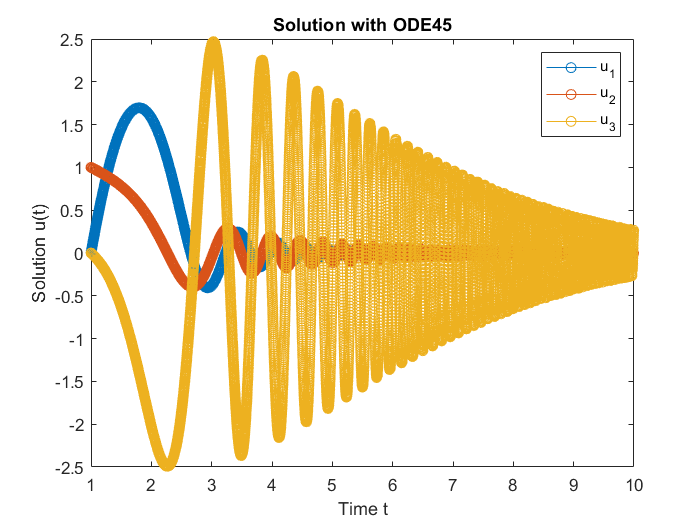


plot(t,u(:,1),'-o',t,u(:,2),'-o',t,u(:,3),'-o')
title('Solution with ODE45');
xlabel('Time t');
ylabel('Solution u(t)');
legend('u_1','u_2','u_3')

function dxdt = vdp1(t,u)
dxdt=[-t*u(1)+4*(t^0.5)*u(2); -0.5*((t/2)^0.5)*u(2)+(t/4)*u(3) ; -1/8*(1+4*(t^4))*u(2)];


end